%% This function calls all other functions, accepts the array to make the bifurcation
clear all
global cds
[x,v,s,h,f] = parameters; 

x_init =     1.8016
  244.4334


first point found
tangent vector to first point found
label = LP, x = ( 43.169371 185.362718 0.068975 )
a=1.119415e-03
label = LP, x = ( 106.319701 129.706196 0.100898 )
a=-4.135232e-04
label = LP, x = ( 132.942639 105.715130 0.098695 )
a=4.503082e-04
Neutral saddle
label = H , x = ( 113.863531 70.777783 0.123326 )
label = LP, x = ( 84.630140 56.729666 0.135453 )
a=6.933513e-04
label = LP, x = ( 74.719203 49.664183 0.134484 )
a=-9.289066e-04

elapsed time  = 16.6 secs
npoints curve = 30000


[x,v,s,h,f]=cont(x,v,s,h,f,cds);

start computing extended curve
Neutral saddle
label = H , x = ( 82.580256 37.470381 0.148775 )
label = LP, x = ( 98.931897 33.006819 0.154844 )
a=-1.389284e-03

elapsed time  = 20.0 secs
npoints curve = 60000


a = x(3,:); %bifurcation parameter
% this number should be # species +1, since there are 2 species A and B now, a=x(3,1) 
b = x(1,:); %x(1) = A, x(2) = B
% Species that you want to plot against bifucation parameter.
% The order of speices is decided by the 
c = a;

 The struct 's' already has the set of indices that this code is trying to compute.



not_stable=[];
k=length(a);

for j = 1: 1: k-1
    
    if f(1,j)>0 || f(2,j) >0 
        
        not_stable=[not_stable;j];
        
    end
end





%% Plotting the figure:
figure1 = figure('Color',[1 1 1],'units','normalized','outerposition',[0 0 1 1]);
% set(gcf, 'Position',  [100, 100, 500, 400]);
axes1 = axes;
hold(axes1,'on');
% plotting stable and unstable branches in different colors:
%first all of it
plot(c,b,'r','LineWidth',5);
ind=[s.index];
n=length(ind);
%Marking the singularities
 for i= 2:1:n-1 %I'm skipping over the first and last singularities because they're just the first and last points of continuation
     plot(c(ind(i)),b(ind(i)),'k*','MarkerSize',10,'LineWidth',5);
%      text(c(ind(i)),b(ind(i)),s(i).label,'FontSize',30);
     
 end
 %Now we make a list of the unstable points
 l=length(not_stable);
 c_ns=zeros(1,l);
 b_ns=zeros(1,l);
 for k=1:1:l
     c_ns(k)=c(not_stable(k));b_ns(k)=b(not_stable(k));
 end
 %And finally we plot the unstable points over the stable points in a
 %diffnt colour
 scatter(c_ns,b_ns,'b','LineWidth',1);
 

hold off; 


% Control over axes and labels:
ylim([0 220]);
xlim([0.0,0.2]);
ylabel('A','FontName','Arial','Fontweight','bold','FontSize',22);
xlabel('\gamma_A','FontName','Arial','Fontweight','bold','FontSize',22);
ax = gca;
ax.FontSize=12

ax =   Axes with properties:

             XLim: [0 0.2000]
             YLim: [0 220]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


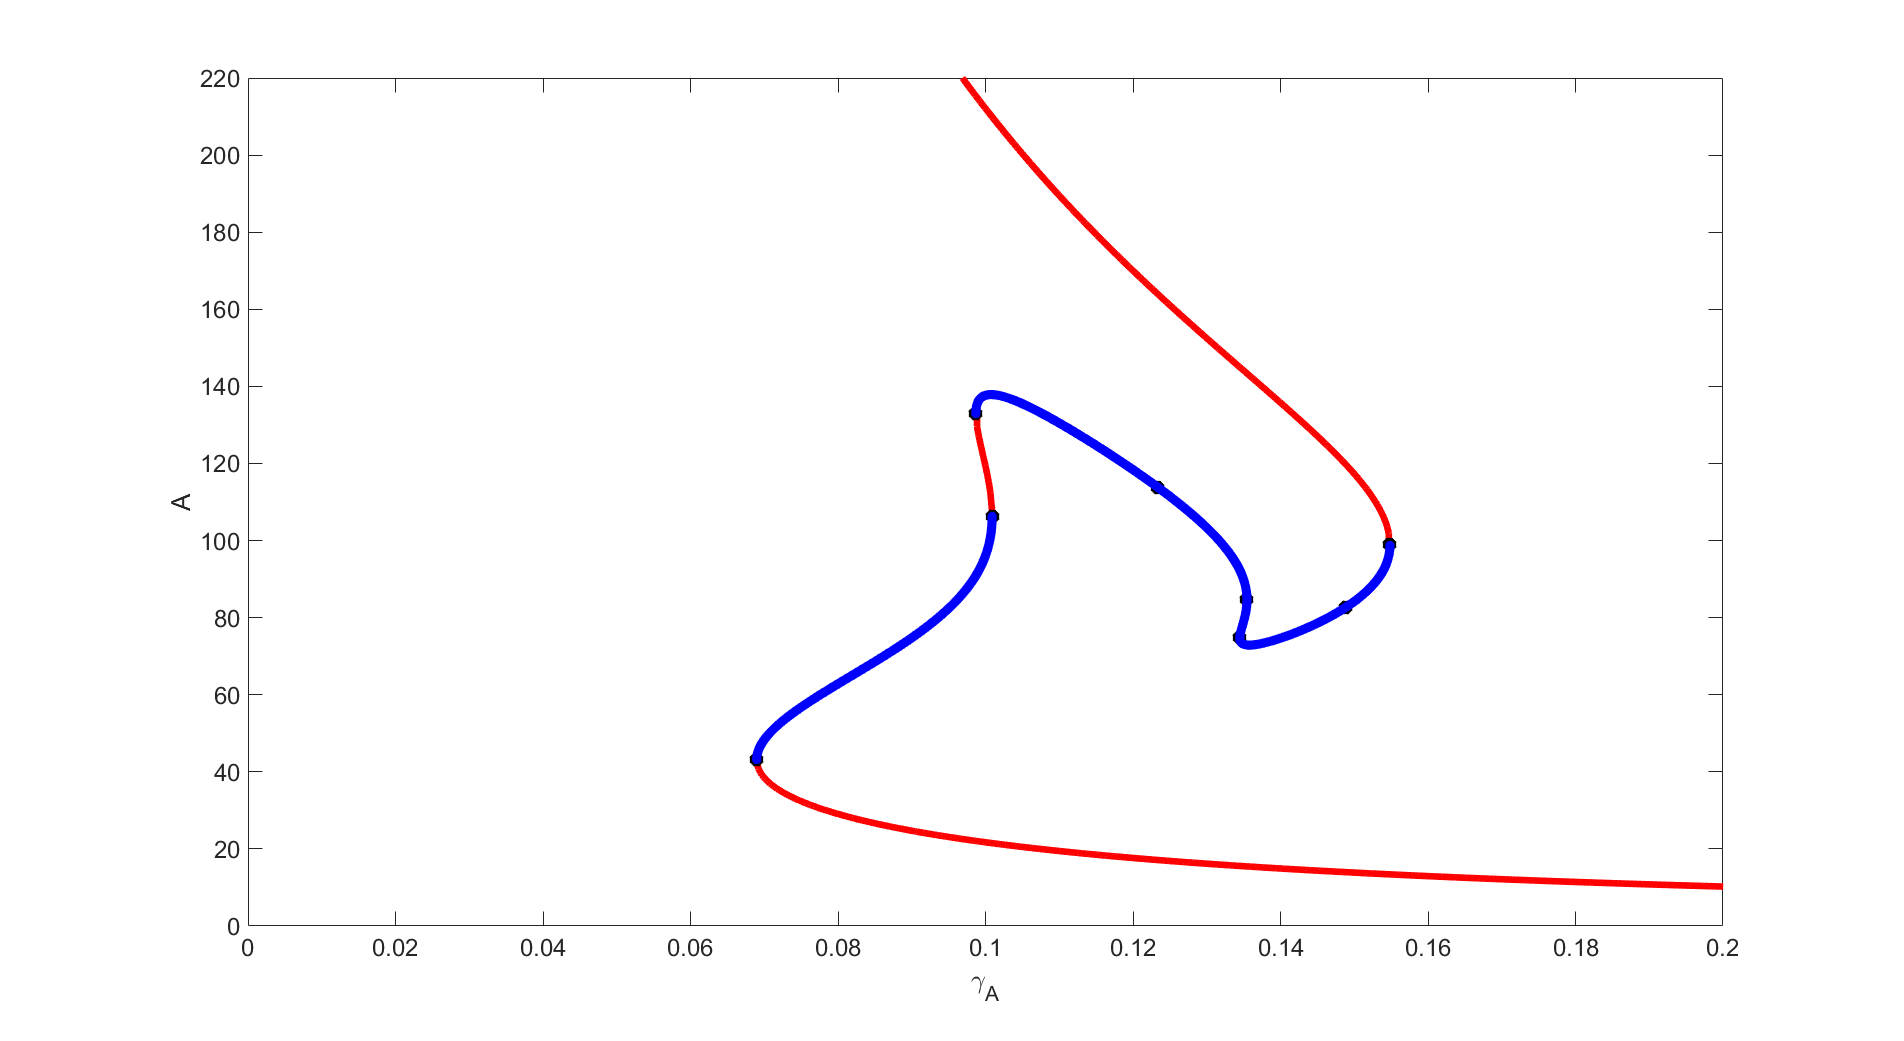

%Set the remaining axes properties
box(axes1,'on');
set(axes1,'FontName','Arial','FontSize',18);
%% Save the figure:
saveas(gcf,"bifurcation.png")